clear all;
close all;
clc

## DH-Table for the Manipulator (Standard)

% [Theta: Joint Angle, d: link_offset, a: link_length, alpha: Link_twist]

dh = [0, 1, 0, -pi/2; ...
      0, 0, 2, 0;...
      0, 0, 1, pi/2;...
      0, 0, 1, 0;]

dh =          0    1.0000         0   -1.5708
         0         0    2.0000         0
         0         0    1.0000    1.5708
         0         0    1.0000         0



R1 = SerialLink(dh,'name', 'TutorialBot')

R1 = 
TutorialBot:: 4 axis, RRRR, stdDH, slowRNE                       
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          1|          0|    -1.5708|          0|
|  2|         q2|          0|          2|          0|          0|
|  3|         q3|          0|          1|     1.5708|          0|
|  4|         q4|          0|          1|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+


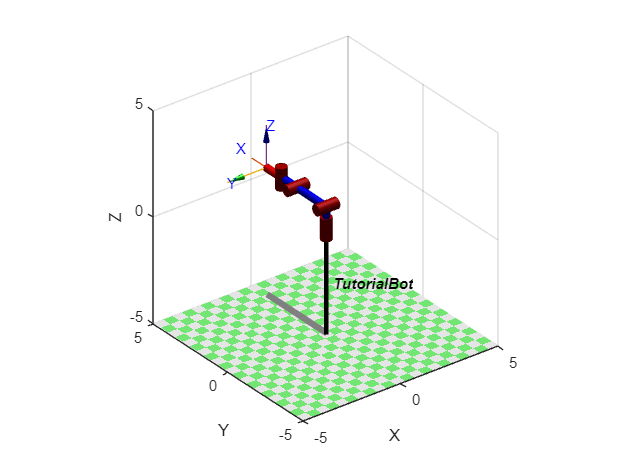


figure(1)
R1.plot([pi/2,0,0,0])

## Simulating FK

theta1 = 0

theta1 = 0

theta2 = 0

theta2 = 0

theta3 = 0

theta3 = 0

theta4 = 0

theta4 = 0

step = 5

step = 5

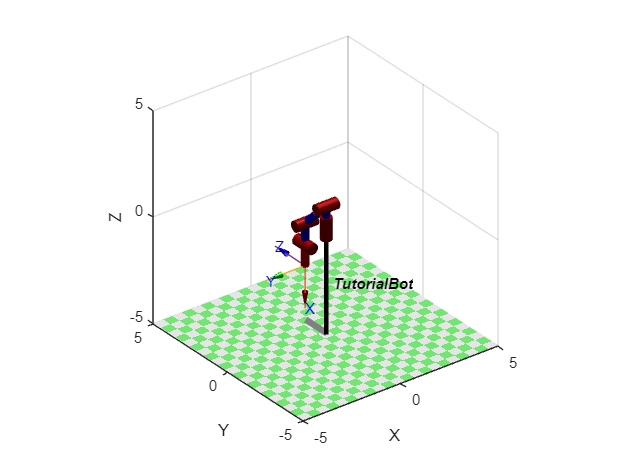


while (theta1 < 90)
    theta1 = theta1 + step;
    R1.plot([deg2rad(theta1),deg2rad(theta2),deg2rad(theta3),deg2rad(theta4)])
end

while (theta3 < 45)
    theta3 = theta3 + step;
    R1.plot([deg2rad(theta1),deg2rad(theta2),deg2rad(theta3),deg2rad(theta4)])
end

while (theta2 < 45)
    theta2 = theta2 + step;
    R1.plot([deg2rad(theta1),deg2rad(theta2),deg2rad(theta3),deg2rad(theta4)])
end

## Simulating IK

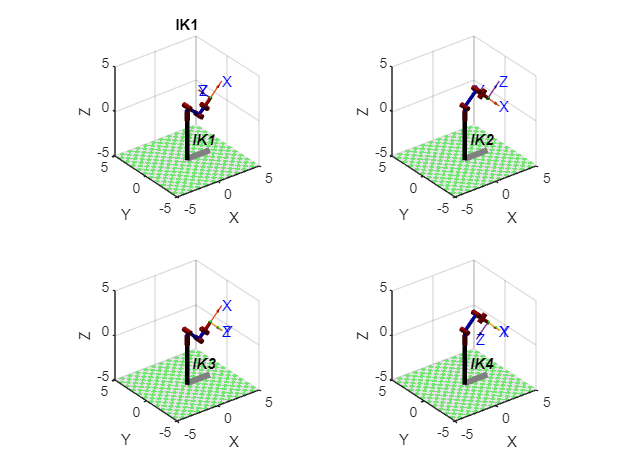

figure(2)

R1 = SerialLink(dh,'name', 'IK1');
subplot(2,2,1)
title('IK1')
R1.plot([0,pi/4,-pi/2,0])
plot_sphere([2*sqrt(2),0,1],.2,'g')

R2 = SerialLink(dh,'name', 'IK2');
subplot(2,2,2)
R2.plot([0,-pi/4,pi/2,0])
plot_sphere([2*sqrt(2),0,1],.2,'g')

R3 = SerialLink(dh,'name', 'IK3');
subplot(2,2,3)
R3.plot([pi,3*pi/4,pi/2,0])
plot_sphere([2*sqrt(2),0,1],.2,'g')

R4 = SerialLink(dh,'name', 'IK4');
subplot(2,2,4)
R4.plot([pi,-3*pi/4,-pi/2,0])
plot_sphere([2*sqrt(2),0,1],.2,'g')